imds = imageDatastore("/fARBOD/IP - HW1/IP - HW3/ALL_IDB2/img/", ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
inputSize = [228 228];
imds.ReadFcn = @(loc)imresize(imread(loc),inputSize);
labelCount = countEachLabel(imds)

labelCount = 2×2 table
    Label    Count
    _____    _____

      1       130 
      2       130 


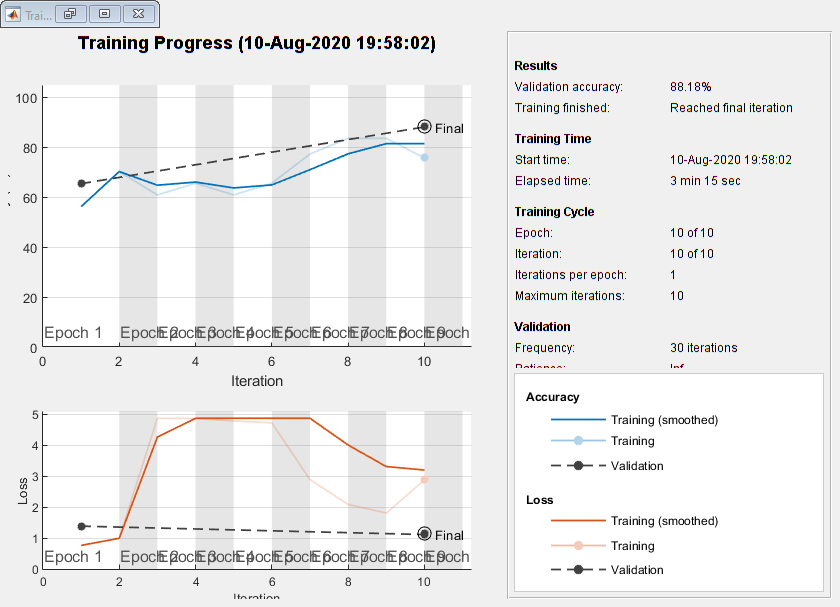

img = readimage(imds,1);
numTrainFiles = 100;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');
layers = [
    imageInputLayer([228 228 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];
options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.8818